# EJERCICIO 2

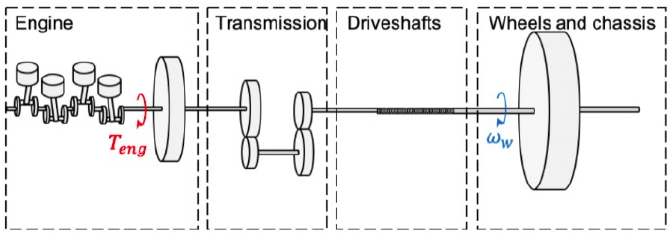

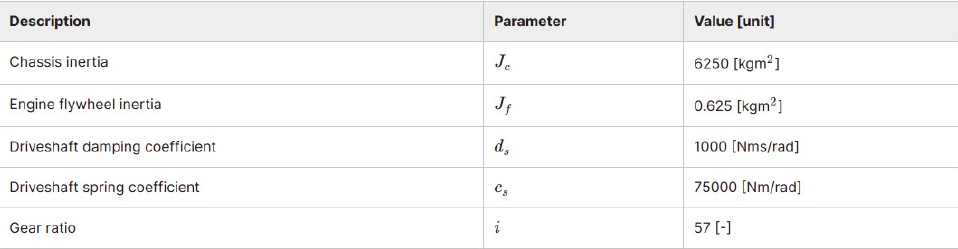

clc; clear; close all;
Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
GR = 57; % gear ratio

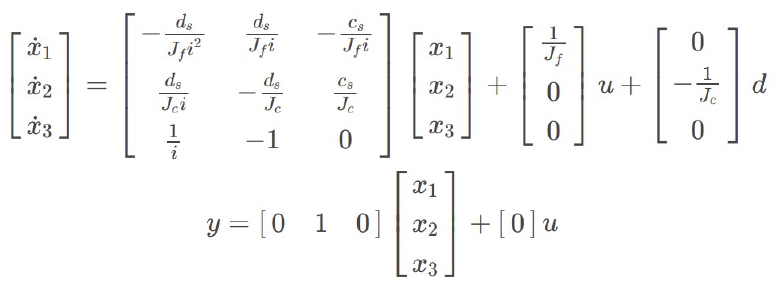

A  = [-ds/(Jf*GR^2) ds/(Jf*GR) -cs/(Jf*GR)
       ds/(Jc*GR)  -ds/(Jc)    cs/Jc
        1/GR           -1         0         ];
Bu = [1/Jf 0  0]';
Bd = [0 -1/Jc 0]';
Cp = [0   1   0];

## **1. Definición de los polos.**

Ubicar dos polos con:

wn   = 6;
zeta = 1/sqrt(2);
p1   = -wn*zeta + i*wn*sqrt(1-zeta^2);
p2   = p1';

El tercer polo se debe ubicar en:

p3   = -2*zeta*wn;

## 2. Encuentre el valor de la matriz K de realimentación por el método de Ackermann

K = acker(A, Bu, [p1 p2 p3])

K = 	1.0e+03 *

    0.0102    0.3255    1.9591


## 3. Encuentre el valor de kr.

kr = 1/(Cp*(-(A-Bu*K)\Bu))

kr = 906.8644

## 4. Encuentre los autovalores del sistema a lazo cerrado.

eig(A-Bu*K)

ans =   -8.4853 + 0.0000i
  -4.2426 + 4.2426i
  -4.2426 - 4.2426i


p1

p1 = -4.2426 + 4.2426i

p2

p2 = -4.2426 - 4.2426i

p3

p3 = -8.4853

# EJERCICIO 3

B  = [Bu Bd];                  % Put the B and H matrix together as one matrix B1 (for Simulink implementation purposes) 
C  = eye(3);                   % Output all state variables from the model
D  = zeros(3, 2);              % Corresponding D matrix
x0 = [120 2 0]';               % Initial conditions for the state variables

### Simulación

sim('Driveline_ctrl_sim');

tEngineSpeedMonitor   = EngineSpeedMonitor.time;
EngineSpeed           = EngineSpeedMonitor.signals.values;

tWheelSpeedMonitor    = WheelSpeedMonitor.time;
WheelSpeed            = WheelSpeedMonitor.signals.values;

tTorqueMonitor        = TorqueMonitor.time;
Torque                = TorqueMonitor.signals.values;

tControlSignalMonitor = ControlSignalMonitor.time;
ControlSignal         = ControlSignalMonitor.signals.values;

### Resultados

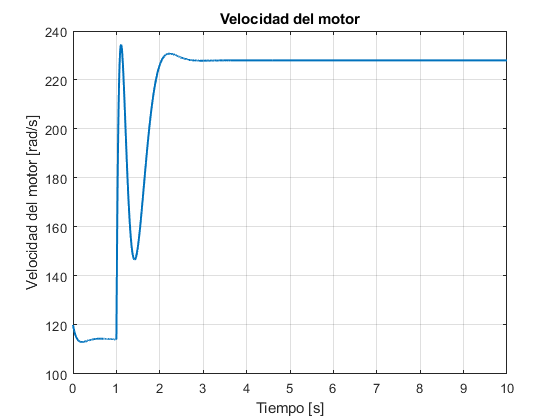

figure;
plot(tEngineSpeedMonitor, EngineSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del motor [rad/s]');
title('Velocidad del motor');
grid on;

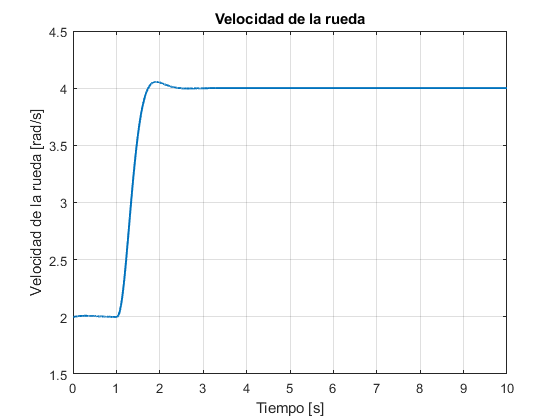


figure;
plot(tWheelSpeedMonitor, WheelSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad de la rueda [rad/s]');
title('Velocidad de la rueda');
grid on;

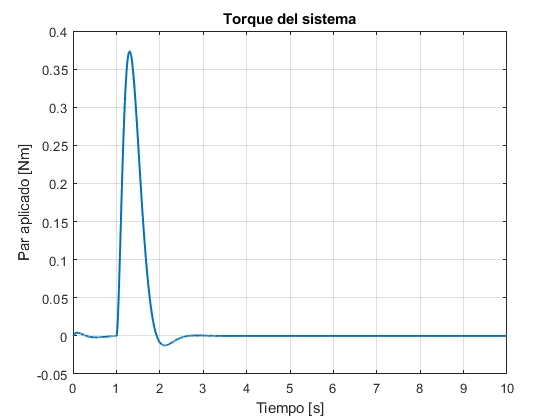


figure;
plot(tTorqueMonitor, Torque, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Par aplicado [Nm]');
title('Torque del sistema');
grid on;

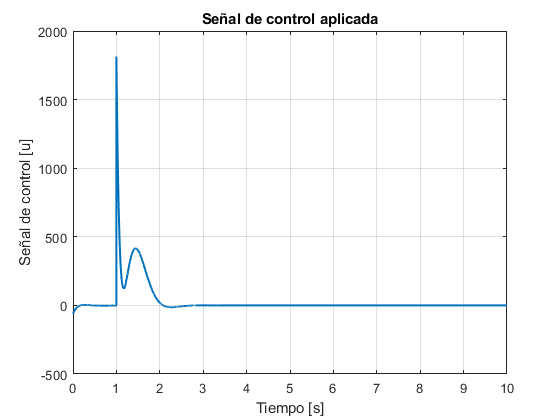


figure;
plot(tControlSignalMonitor, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u]');
title('Señal de control aplicada');
grid on;

# PREGUNTAS

## 1.Se han reducido las oscilaciones en la velocidad del vehículo.

Si.

## 2.La velocidad del motor está oscilando.

Si un poco en el transitorio luego no.

## 3.Se mejora la capacidad de conducción del vehículo.

si (mas o menos porque u queda parecido).

## 4. El mismo controlador se puede utilizar para todas las marchas.

No, cambia la dinámica de planta.